# **Lab 2**

# Problem 1

In lecture and homework we explored how the convolution can be used to calculate the probability of a sum or average. For this problem we are going to imagine that we are looking for gamma-ray sources (e.g. with the [Fermi telescope](https://fermi.gsfc.nasa.gov)). In this kind of telescope there is a background of cosmic-rays (electrons and protons, mostly) that provides a discrete noise term across the sky that precisely follows a Poisson distribution. To detect a gamma-ray source, you need to ask what is the probability that the cosmic-ray background would have given you a measurement as signal-like or more than the signal that you received.

To set up the problem, assume in 1 day the average cosmic-ray background is some number X (pick someting btwn 0.5 and 10, with different values for you and your lab partner); and the average number of gamma-rays emitted by your hypothetical source is Y (pick something larger than X).

## A) Show how the probability distribution of the background changes as you integrate (sum) for more days.

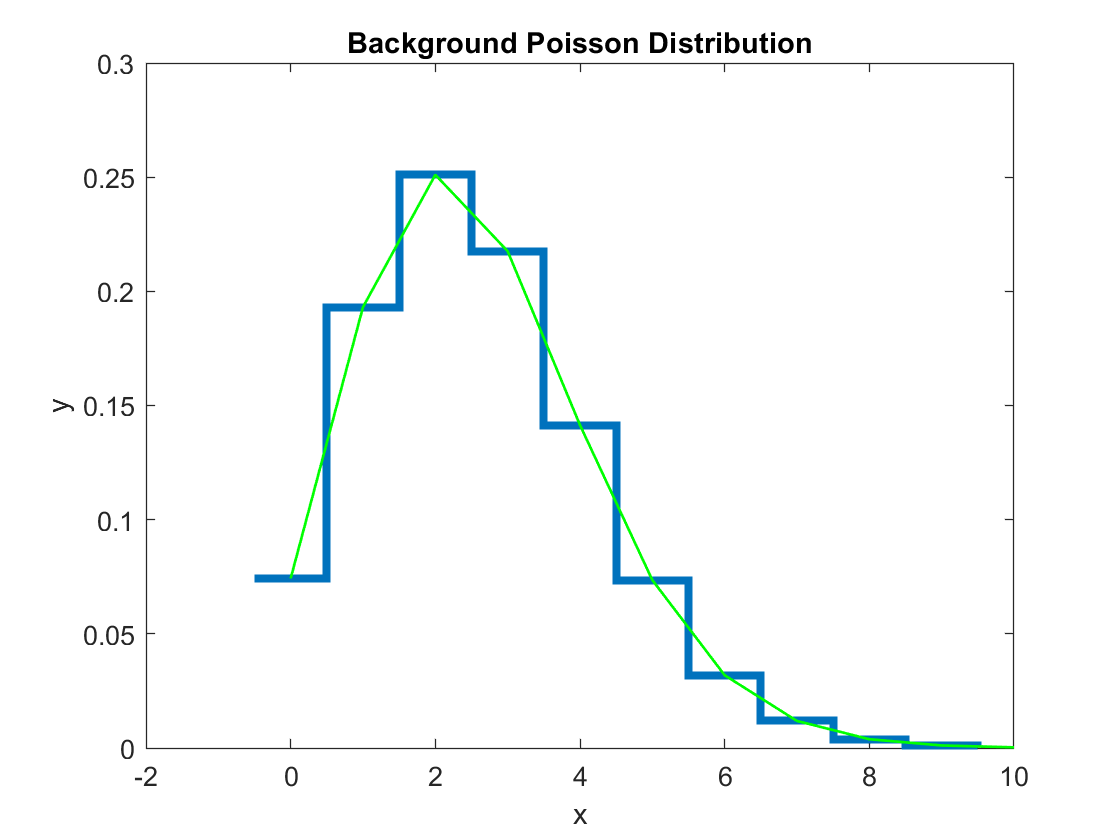

X = 2.6;
Y = 5.9;

xvals = 0:10;
poisson = makedist("Poisson","lambda",X);
funct = pdf(poisson,xvals);

stairs(xvals-0.5,funct,"LineWidth",3)
hold on
plot(xvals,funct,"LineWidth",1,"Color","green")
hold off

title('Background Poisson Distribution')
xlabel('x')
ylabel('y')

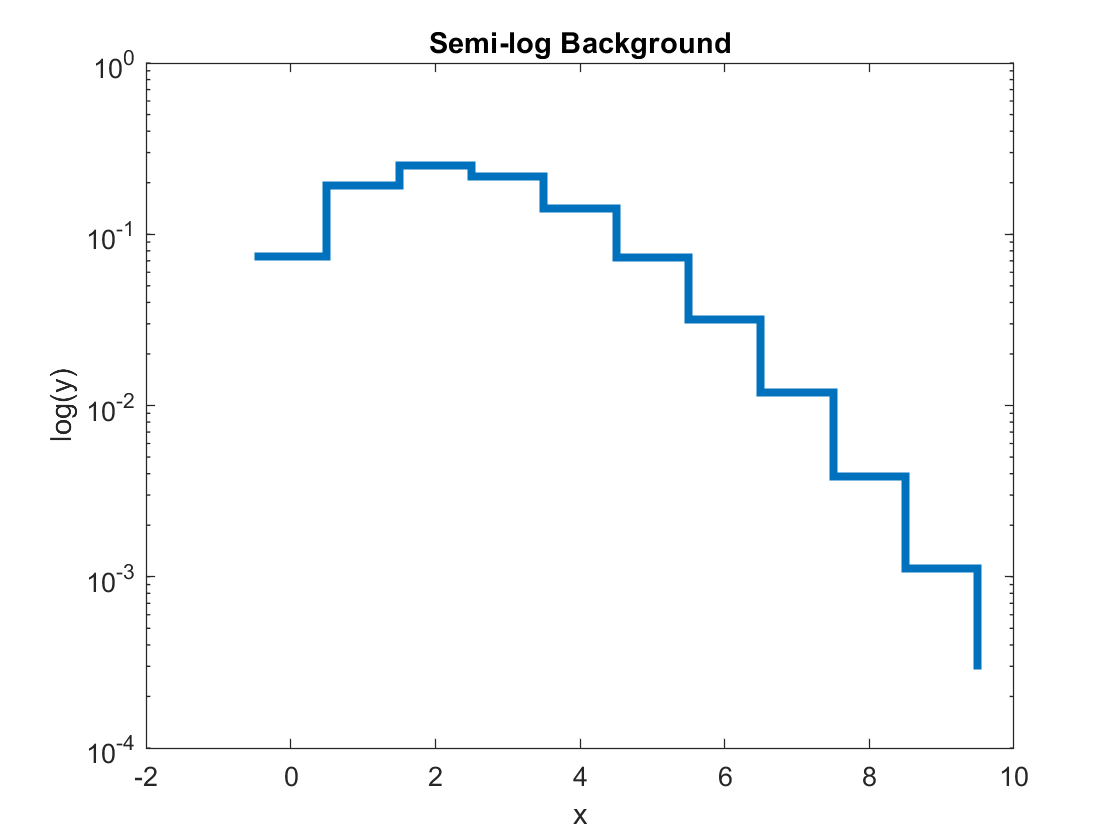


%semi-log axis
stairs(xvals-0.5,funct,"LineWidth",3)
set(gca,'YScale','log')

title('Semi-log Background')
xlabel('x')
ylabel('log(y)')

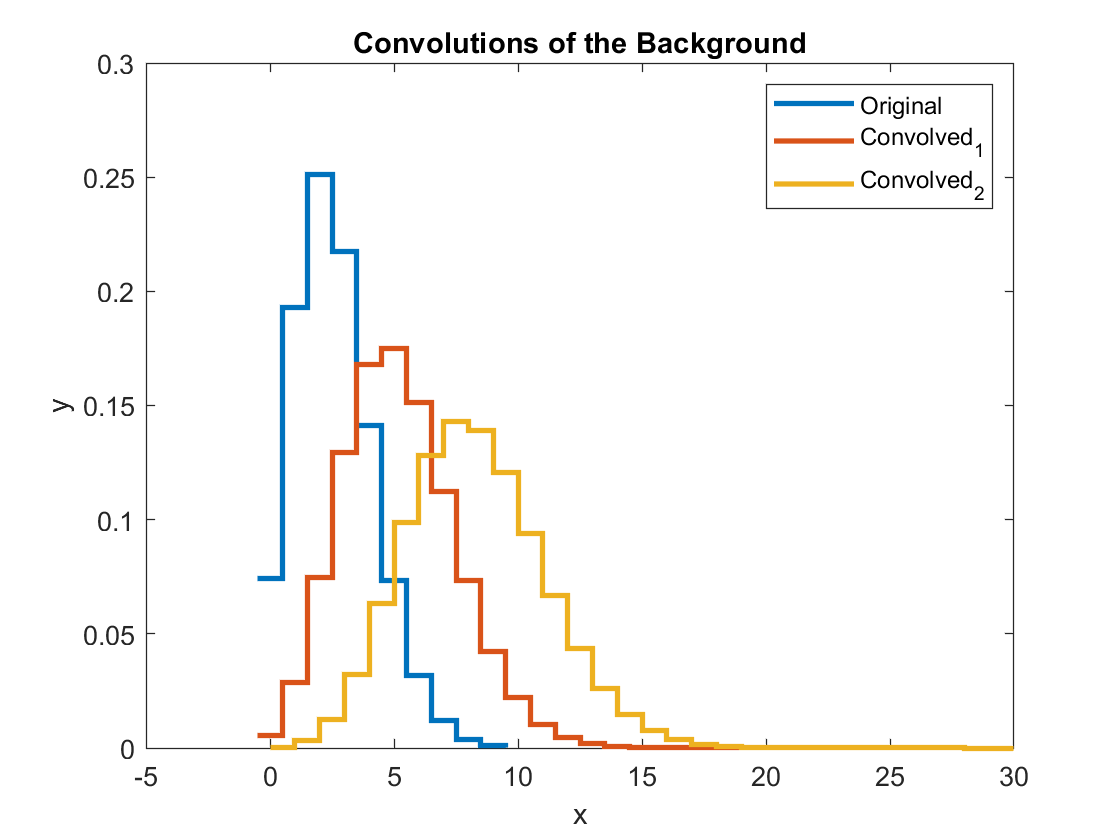


stairs(xvals-0.5,funct,"LineWidth",2)
hold on

%1st convolution
convol = conv(funct,funct);

cxvals = 0:length(convol)-1;
stairs(cxvals-0.5,convol,"LineWidth",2)

%2nd convolution
convol2 = conv(convol,funct);

c2xvals = 0:length(convol2)-1;
stairs(c2xvals,convol2,"LineWidth",2)

legend("Original","Convolved_1","Convolved_2")
title('Convolutions of the Background')
xlabel('x')
ylabel('y')

hold off


sum(convol2)

ans = 0.9997

sum(convol)

ans = 0.9998

sum(funct)

ans = 0.9999

%all sums are close to 1 --> normalized :)

%mean for original distribution
weighted = zeros(1,length(xvals));

for i = 1:length(xvals)
    weighted(i) = funct(i)*xvals(i);
end

avg_val = sum(weighted)

avg_val = 2.5990


%mean for convolved dist
weighted_c = zeros(1,length(cxvals));

for i = 1:length(cxvals)
    weighted_c(i) = convol(i)*cxvals(i);
end

avg_val_c = sum(weighted_c)

avg_val_c = 5.1976


%mean for second convolution
weighted_c2 = zeros(1,length(c2xvals));

for i = 1:length(c2xvals)
    weighted_c2(i) = convol2(i)*c2xvals(i);
end

avg_val_c2 = sum(weighted_c2)

avg_val_c2 = 7.7957


length(funct)

ans = 11

length(convol)

ans = 21

length(convol2)

ans = 31

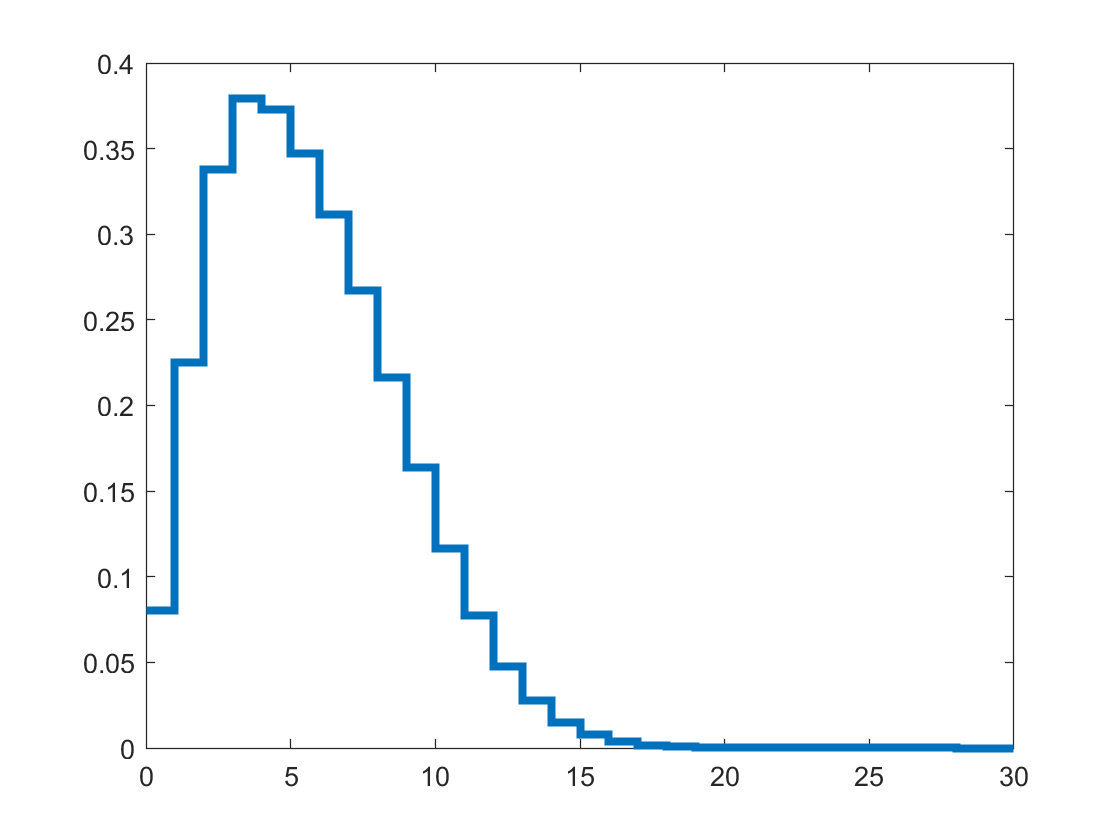


summed = zeros(1,31);

for i = 1:11
    summed(i) = funct(i) + convol(i) + convol2(i);
end

for k = 12:21
    summed(k) = convol(k) + convol2(k);
end

for j = 22:31
    summed(j) = convol2(j);
end

stairs(c2xvals,summed,"LineWidth",3)


%Finding avg value of the summed distribution
weighted_summed = zeros(1,length(c2xvals));

%making sum of the y values 1

BASE = summed/sum(summed);

for i = 1:length(c2xvals)
    weighted_summed(i) = BASE(i)*c2xvals(i);
end

avg_val_summed = sum(weighted_summed)

avg_val_summed = 5.1983

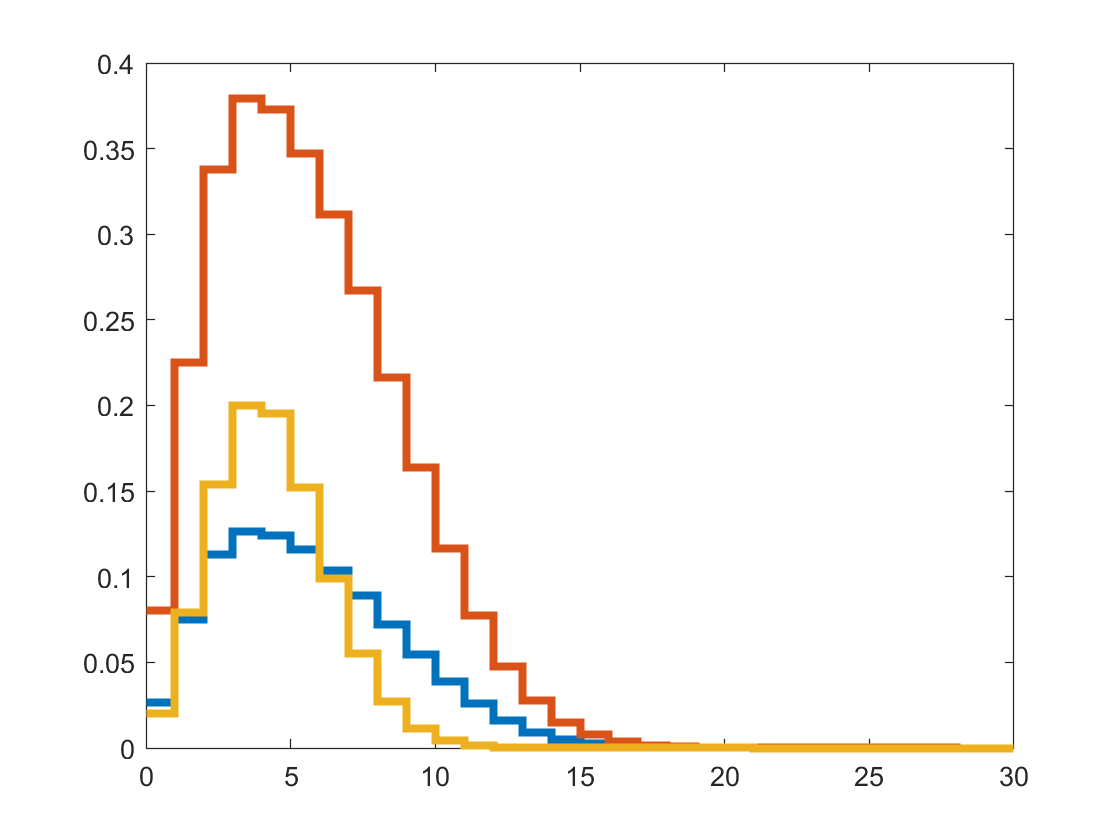


stairs(c2xvals,BASE,"LineWidth",3)
hold on
stairs(c2xvals,summed,"LineWidth",3)
poisson_2 = makedist("Poisson","lambda",3.9);
stairs(c2xvals,pdf(poisson_2,c2xvals),"LineWidth",3)
hold off

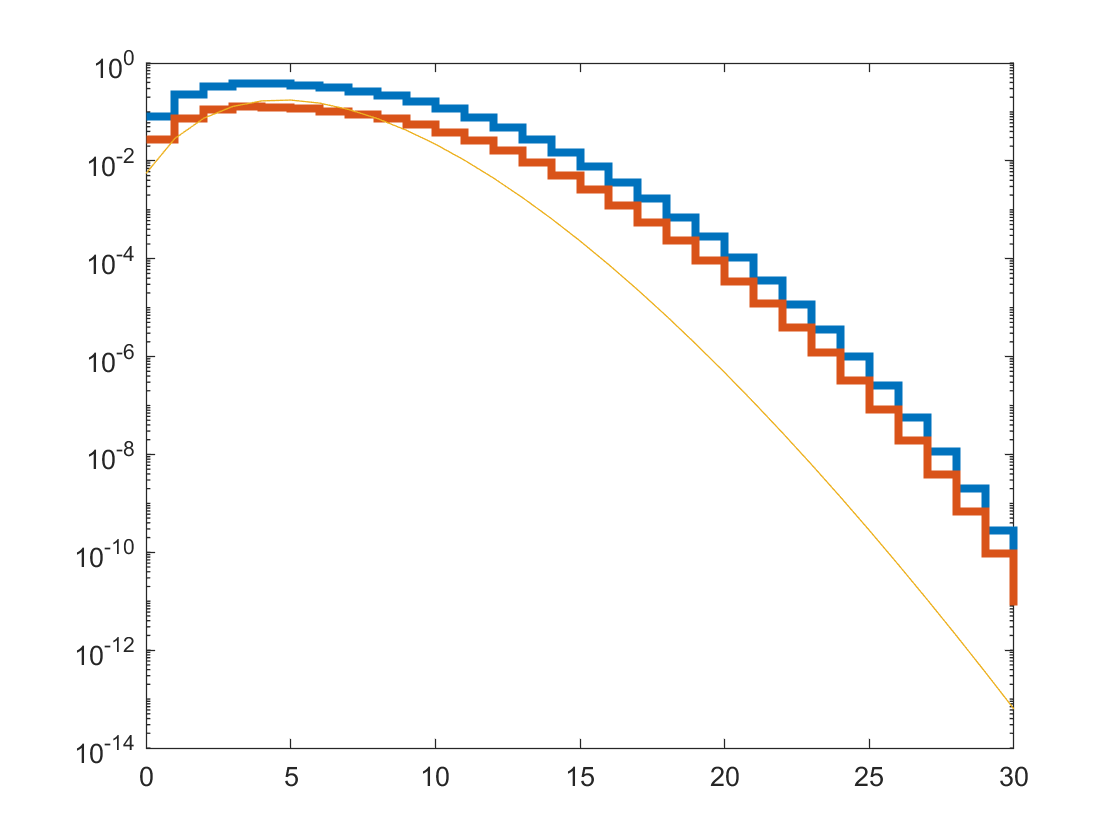


stairs(c2xvals,summed,"LineWidth",3)
hold on
stairs(c2xvals,BASE,"LineWidth",3)
poisson_2 = makedist("Poisson","lambda",avg_val_summed);
plot(c2xvals,pdf(poisson_2,c2xvals))
set(gca,'YScale','log')
hold off

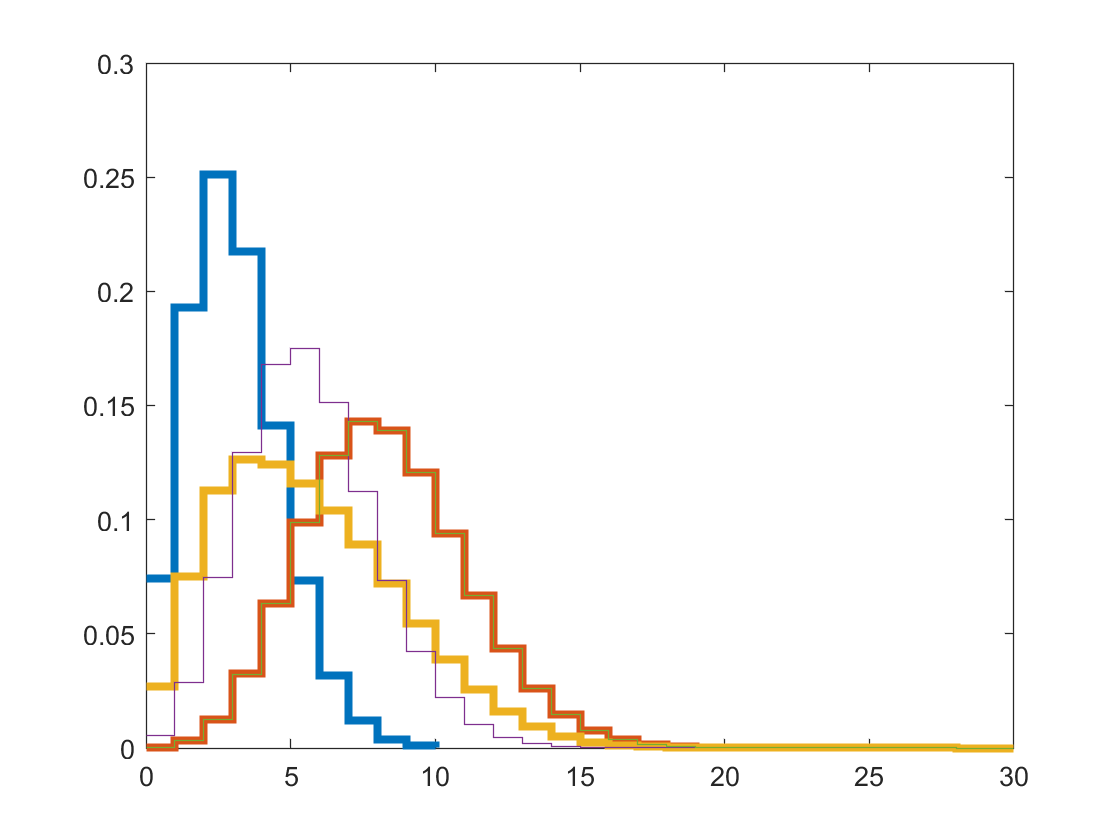


%Trying a different method for summing

resolution = 1;
xmax = 10;
xmin = 0;
x = xmin:resolution:xmax;

logP = makedist("Poisson",'lambda',X);

base = pdf(logP,x);
base = base/sum(base); %because we've quantized the pdf, we need to renormalize 
% to keep the convolution integral from blowing up
comb = base;

for i = 2: 3
    comb = conv(comb,base,"full");
end

stairs(x,base,"LineWidth",3)
hold on

cx = xmin*i:resolution:xmax*i;
stairs(cx,comb,"LineWidth",3)
stairs(c2xvals,BASE,"LineWidth",3)
stairs(cxvals,convol)
stairs(c2xvals,convol2)
hold off

**NOTE: MAKE A FOR LOOP TO CONVOLVE AND TO FIND THE AVERAGE VALUES!!!!!!**

**USE CLASS 4 CODE FOR HOW TO DO AVERAGE AND SUM!!!!!!**

## B) Show that after 5 days, the summed probability distribution is still a Poisson distribution. Explain why this makes sense from a mathematical and conceptual point of view. 

convolution: perform 4 times

overlay with poisson with lambda of found average value

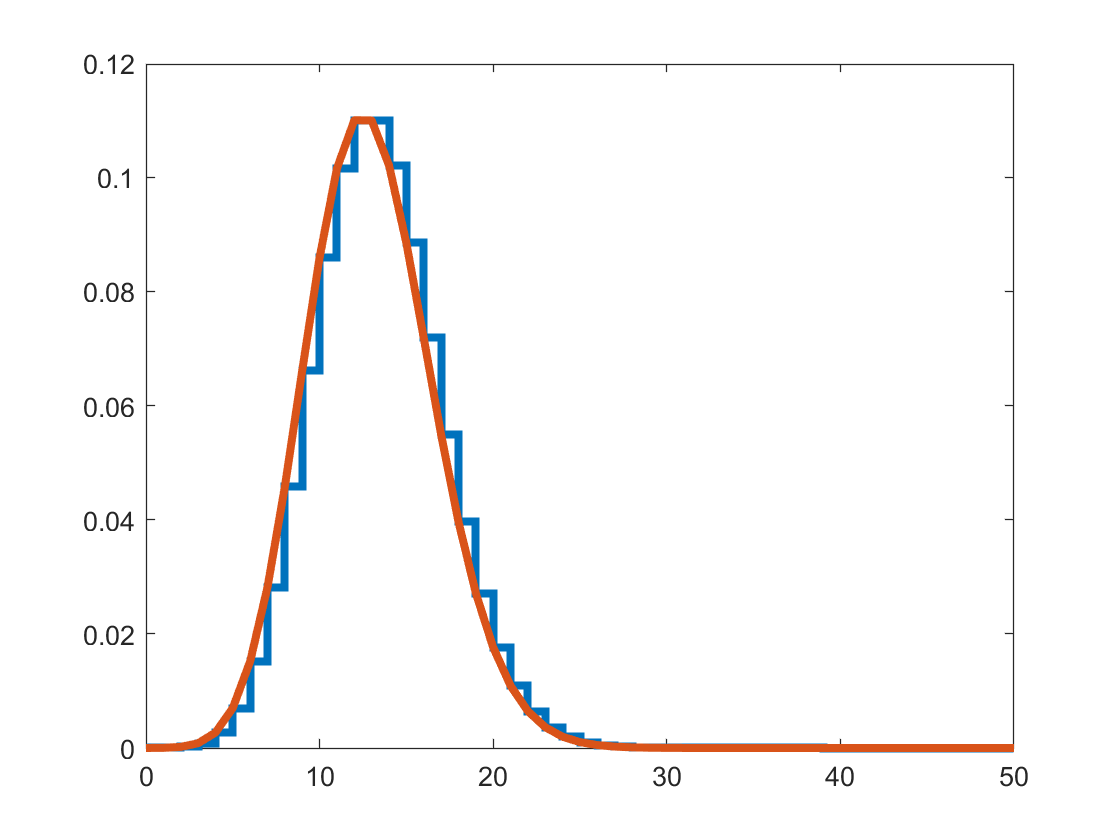

res = 1;
xmax_5 = 10;
xmin_5 = 0;
x = xmin_5:res:xmax_5;

logP = makedist("Poisson",'lambda',X);

base = pdf(logP,x);
base = base/sum(base);
comb = base;

for i = 2:5
    comb = conv(comb,base,"full");
end

cx_5 = xmin*i:res:xmax*i;
stairs(cx_5,comb,"LineWidth",3)
hold on

weighted_5 = zeros(1,length(cx_5));

for i = 1:length(cx_5)
    weighted_5(i) = comb(i)*cx_5(i);
end

lambda = sum(weighted_5);

poisson_5 = makedist("Poisson","lambda",lambda);
plot(cx_5,pdf(poisson_5,cx_5),"LineWidth",3)
hold off

Explain why this makes sense from a mathematical and conceptual point of view

## C) Show how the probability distribution evolves as you *average* days. Calculate for many different ranges of days, and explore the shape of the distribution as the number of days becomes larger. Discuss this in relation to both B) and the central limit theoem.

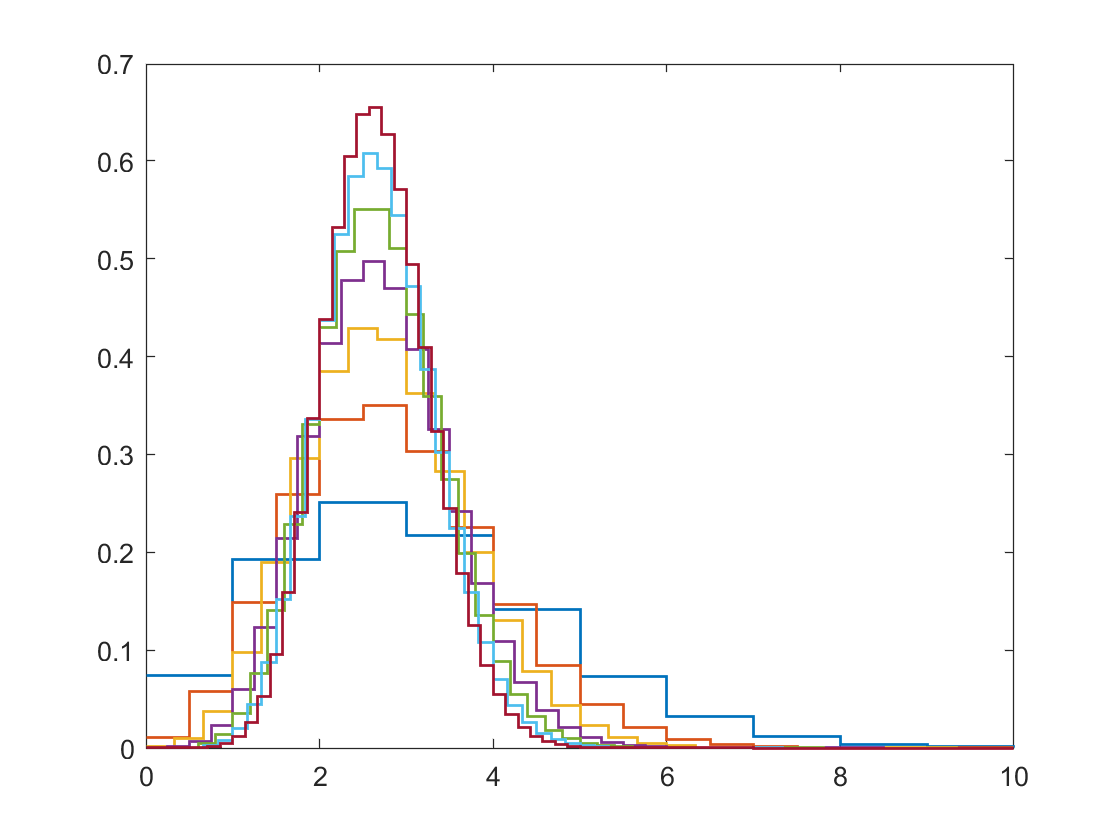

res = 1;
xmax = 10;
xmin = 0;
x = xmin:res:xmax;

logP = makedist("Poisson",'lambda',X);

day1 = pdf(logP,x);
day1 = day1/sum(day1);
dayn = day1;

stairs(x,day1,"LineWidth",1)
hold on

for i = 2:7
    dayn = conv(dayn,day1,"full");
    
    x_n = xmin:res/i:xmax;
    stairs(x_n,i*dayn,"LineWidth",1)
end

%by plotting i*dayn, I'm ensuring the area under the curve is still equal
%to 1, since the resolution step size is 1/i

hold off

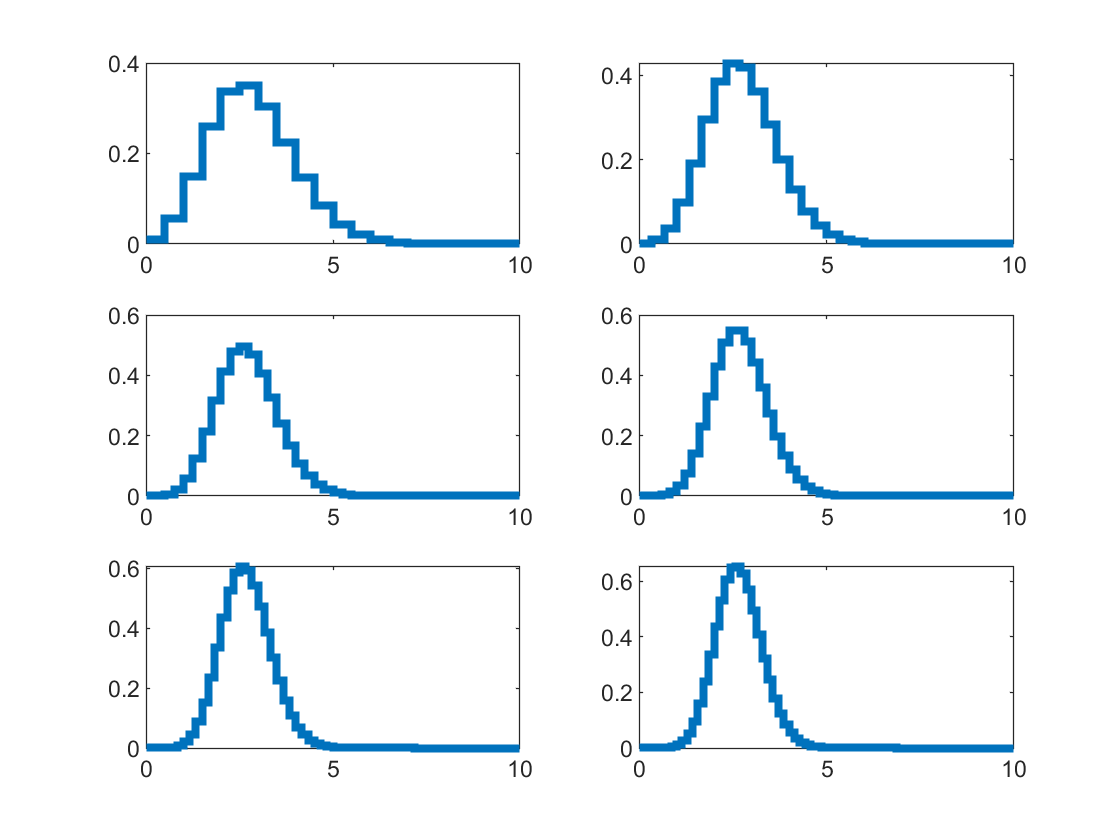


day1 = pdf(logP,x);
day1 = day1/sum(day1);
dayn = day1;

for i = 2:7
    dayn = conv(dayn,day1,"full");
    
    subplot(3,2,i-1)
    x_n = xmin:res/i:xmax;
    stairs(x_n,i*dayn,"LineWidth",3)
end

Talk about explanations and stuff -- more plots (log, gaussian) to make point?

## D) Pick some number of days N, and assume you saw Y*N gamma rays from your source. Calculate the 'sigma' of your observation. [In reality the number of gamma-rays seen from a source will also fluctuate, but we're going to ignore that complication for a couple of labs.]

- you see Y*N gamma rays... 

- use the summed?? distribution (maybe add up all of the distributions without averaging them)

- find sigma from that ... ... ... 

# Problem 2

Pick a skewed continuous distribtuion, such as a Rayleigh, that describes your background over some observing interval.

## A) Show how the distribution changes as you average over more observing intervals.

ray_res = 0.1;
xmax = 10;
xmin = 0;
x = xmin:res:xmax;

ray = makedist("Rayleigh","b",2);

base_ray = pdf(ray,x);
base_ray = base_ray/sum(base_ray);
avgd = base_ray;

## B) Discuss how the shape changes. Does it approach a Gaussian distribution? If yes, after how many intervals?

# Problem 3

The discovery of optical/infra-red counterparts of Neutron star mergers initially detected with gravity-waves is one of the great discoverys in the last few years ([wikipedia](https://en.wikipedia.org/wiki/GW170817), [scientific paper](https://arxiv.org/abs/1710.05833)), and has ushered in the age of "multi-messenger astrophysics." The science that can be done by matching a gravity-wave signal (directly measures the mass of the neutron stars and their distance) with the optical emisson (redshift, nuclear astrophysics of the resulting explosion) is *staggering*. Lots of science from how the heaviest elements are formed to constraints on Dark Energy.

We're going to explore one of the analysis questions that comes up when looking for the optical counterparts (a new optical source) of a gravity wave signal. For this problem let's assume that we are using an optical telescope with a thermal noise background from the CCD (dark current, particularly an issue with older CCDs and/or infra-red CCDs). After flat-fielding, the background appears as a zero-mean Gaussian with constant width over the image.

## Version 1

You have an alert from [LIGO](https://www.ligo.caltech.edu) that is also seen in with the X-ray/ultra-violet satellite [SWIFT](https://swift.gsfc.nasa.gov). SWIFT gives you a very precise location, so you take an image of that part of the sky. But because of SWIFT's accuracy, you know which pixel in your image to look for a counterpart in.

### A) From looking at all the other pixels in your image, you can measure the width of the background Gaussian distribution X (pick something). Assuming you see a signal of strength Y (pick a floating-point number; optical CCDs are not sensitive enough to count photons so the readings are floating point brightnesses, not integer photons). Calculate the significance of your detection. Can you claim a discovery (traditionally 5-sigma or more)?

## **Version 2**

You have an alert from LIGO, but no associated detection from SWIFT. This could be because it is a black hole-black hole merger, a black hole-neutron star merger (neither seem to emit X-rays or UV light), or it could because SWIFT was indisposed at the time (wrong side of the earth in its orbit). Whatever the cause, you know what region of the sky to look in, but not which pixel.

### B) If you have to look for a signal in 10k pixels, what is the probability distribution of your background? (*Clearly* state the statistical question, then turn that into math using your background distribution from part 1 of this problem.)

### C) Taking your brightest candidate signal from the region (assume it has the same signal as in part 1), calculate the significance of your detection.

# Problem 4

The statistical issue we were exploring in the previous problem is called a **trials factor** (sometimes known as a look-elsewhere effect). This is an important effect, as if you search through a million locations, you would expect to se ~1 one in a million event. However, it is also often over estimated how big an impact this makes on the sensitivity of a search. So in this part of the lab we are going to invert the problem.

Let us again assume we have a Gaussian background (same parameters as Problem 3).

## A) Calculate the signal required for a 5-sigma detection in Version 1

## B) Calculate the signal required for a 5-sigma detection in Version 2

## C) Discuss how much brighter the signal must be for discoverey if you have a trials factor of 10k. Looking at your probability distributions, explain why the sensitivity penalty due to a trials factor is so low.

## D) If you changed the trials factor significantly (orders of magnitude), how large is the effect on your 5-sigma sensitivity threshold?

## Extra credit: If you had a different distribution shape (non-Gaussian), how would that affect the sensitivity penalty of many trials? Clearly explain.